# ENS - Homework 2

Creato da: Dandolo Giacomo (S296525) Favellato Francesco (S312697) Genduso Cristina (S293536)

clear all;
clc;

## Carica audio

[classic, fs_classic] = audioread('audio/the_wormhole.wav');
T_classic = 90;
[rock, fs_rock] = audioread('audio/crazy_train.wav');
T_rock = 296;

## Brano classico

f_c = fs_classic                    % frequenza di campionamento

f_c = 44100

T_0 = 0.000442;                     % durata della porta
N = ceil(T_0 * f_c);                % numero di campioni (porta)
n_p = length(rock) - N;

## Spettro di ingresso

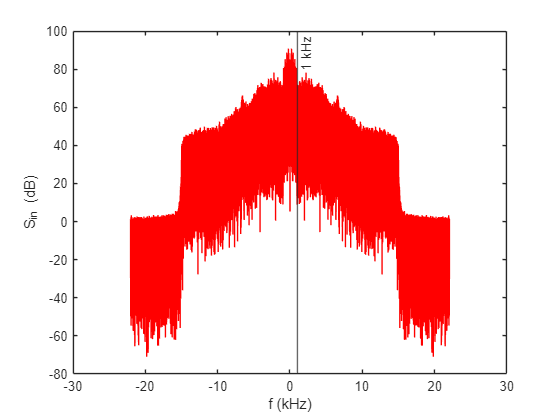

x = rock(1:length(rock));
y = fftshift(abs(fft(x, length(rock))));
n = -(length(rock)/2-1) : (length(rock)/2); 
f = (n/length(rock))*f_c/1000;

S_y = abs(y).^2;
S_y_dB = 10.*log10(S_y);

plot(f, S_y_dB, 'red');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{in} (dB)')

## Spettro di uscita (1)

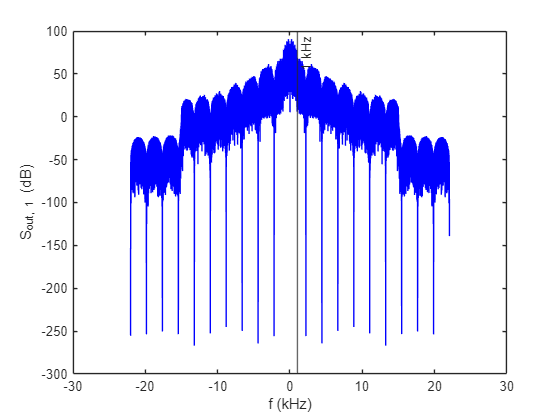

p = [ ones(1, N) zeros(1, n_p) ];     % funzione porta
p = p./sum(p);                        % normalizzazione
x_p = conv(x, p);

y_p = fftshift(abs(fft(x_p, length(rock))));

S_yp = abs(y_p).^2;
S_yp_dB = 10.*log10(S_yp);

% limita y

plot(f, S_yp_dB, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('S_{out, 1} (dB)')

## Funzione di trasferimento (1)

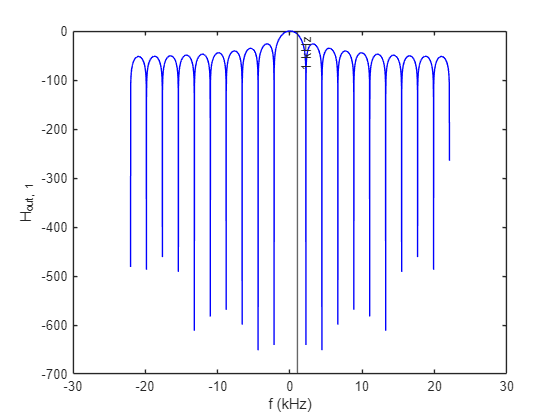

H = 20.*log10(S_yp./S_y);

% limita y

plot(f, H, 'blue');
xline(1, '-', '1 kHz')
xlabel('f (kHz)');
ylabel('H_{out, 1}');

## Spettro di uscita (2)

B = 1000;            % ?
T = 1/(2*B);
func = @(t) (1/T)*sinc(t./T);

x = linspace(-20, 20);
y = func(x-5)

y =    -0.0000   -0.0033   -0.0064   -0.0092   -0.0116   -0.0132   -0.0141   -0.0141   -0.0131   -0.0113   -0.0086   -0.0053   -0.0015    0.0025    0.0066    0.0104    0.0137    0.0162    0.0178    0.0183    0.0176    0.0157    0.0127    0.0087    0.0039   -0.0014   -0.0069   -0.0122   -0.0171   -0.0211   -0.0240   -0.0255   -0.0254   -0.0236   -0.0201   -0.0151   -0.0086   -0.0010    0.0073    0.0158    0.0240    0.0314    0.0375    0.0416    0.0434    0.0425    0.0385    0.0314    0.0211    0.0077


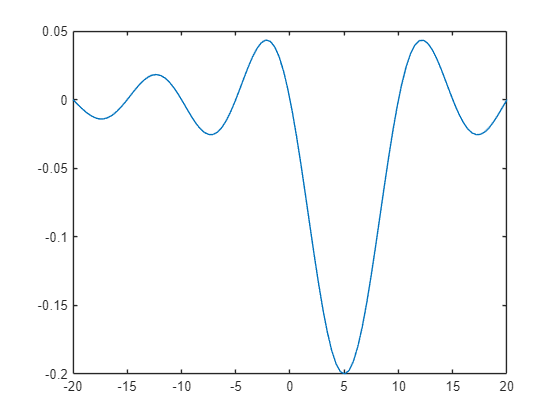

plot(x, y)